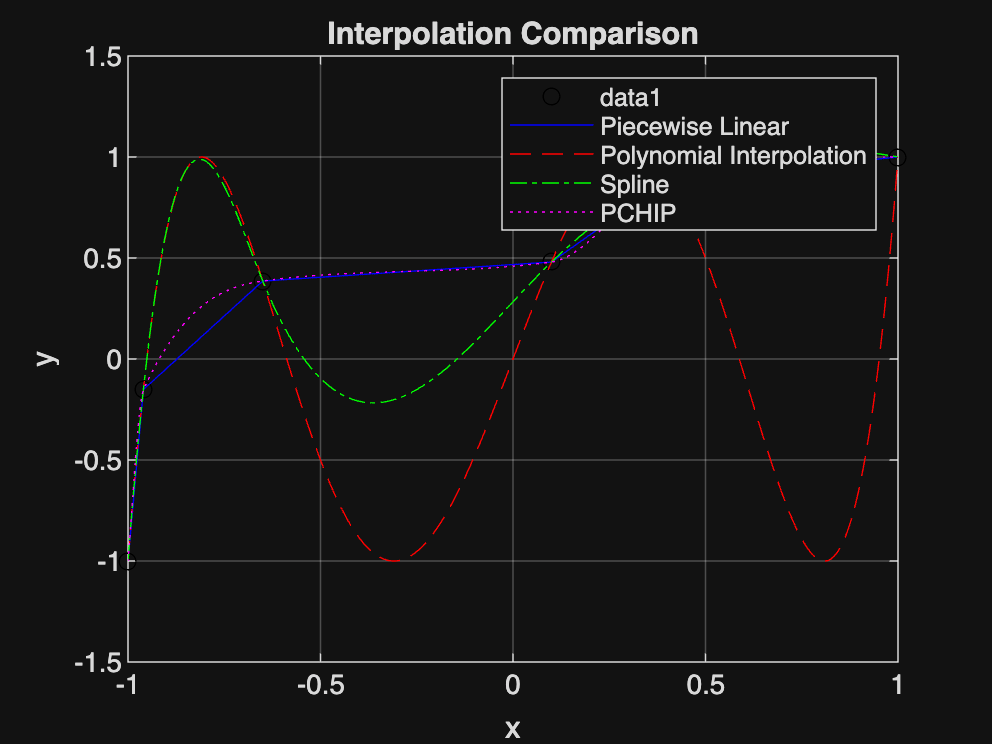

% Given data
x = [-1.00, -0.96, -0.65, 0.10, 0.40, 1.00];
y = [-1.00, -0.1512, 0.3860, 0.4802, 0.8838, 1.00];

% Interpolation range
xx = linspace(-1, 1, 400);

% Interpolation methods
yy_piecelin = interp1(x, y, xx, 'linear');
yy_polyinterp = polyval(polyfit(x, y, length(x)-1), xx);
yy_spline = spline(x, y, xx);
yy_pchip = pchip(x, y, xx);

% Plotting
figure;
plot(x, y, 'ko'); hold on;
plot(xx, yy_piecelin, 'b-', 'DisplayName', 'Piecewise Linear');
plot(xx, yy_polyinterp, 'r--', 'DisplayName', 'Polynomial Interpolation');
plot(xx, yy_spline, 'g-.', 'DisplayName', 'Spline');
plot(xx, yy_pchip, 'm:', 'DisplayName', 'PCHIP');
legend('show');
xlabel('x'); ylabel('y');
title('Interpolation Comparison');
grid on;


% Evaluate all interpolants at x = 3
x_val = 3;
y_piecelin_3 = interp1(x, y, x_val, 'linear', 'extrap');
y_polyinterp_3 = polyval(polyfit(x, y, length(x)-1), x_val);
y_spline_3 = spline(x, y, x_val);
y_pchip_3 = pchip(x, y, x_val);

fprintf('Interpolated values at x = 3:\n');

Interpolated values at x = 3:


fprintf('Piecewise Linear: %.4f\n', y_piecelin_3);

Piecewise Linear: 1.3873


fprintf('Polynomial Interpolation: %.4f\n', y_polyinterp_3);

Polynomial Interpolation: 3363.4187


fprintf('Spline: %.4f\n', y_spline_3);

Spline: 1.1597


fprintf('PCHIP: %.4f\n', y_pchip_3);

PCHIP: -0.8121



% Recover the generating polynomial
% coeffs = polyfit(x, y, length(x)-1);
% fprintf('\nRecovered polynomial coefficients (highest degree first):\n');
% disp(coeffs);
% 
% % Optional: round to nearest integer if it looks close to integer coefficients
% rounded_coeffs = round(coeffs);
% fprintf('Rounded (likely true) integer polynomial:\n');
% disp(rounded_coeffs);

sym_x=sym('x');
p= lagrange_polyinterp1(x,y,sym_x);
simplify(p)

$$ans = \frac{39026359115\,x^{5}}{2438879058}+\frac{32769433\,x^{4}}{48777581160}-\frac{18583954579\,x^{3}}{929096784}-\frac{2429837\,x^{2}}{3576069000}+\frac{97563205703\,x}{19511032464}+\frac{389108}{50809980375}$$

function v = lagrange_polyinterp1(x,f,u)
    n=length(x);
    m=length(u);
    v=zeros(m,1);
    
    for k=1:m
        sum_val=0;
        for j=1:n
            prod=1;
            for i=1:n
                if i~=j
                    prod=prod* (u(k)-x(i)) / (x(j)-x(i));
                end
            end
            sum_val=sum_val+prod*f(j);
        end
        if isa(u, 'sym')
            v=sum_val;
        else
            v(k)=sum_val;
        end
    end 
end
